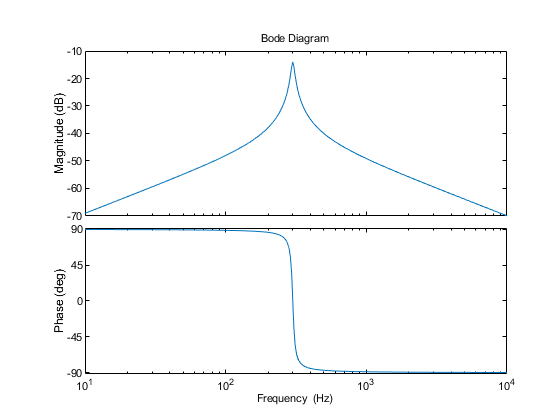

fres=300;
L=50e-3;
imax_des=6;
height=13e-3;
thickness=13e-3;
diameter=63e-3;
magnetic_area=thickness*height;

gap_width=1e-3;
mu0=4*pi*1e-7;
Rmag=gap_width/(mu0*magnetic_area);   %mag reluctance of air gap
Al0=1.4e-3/(11^2);      %Al value of ungapped core 1.4mH @ 11 turns
Al=1/Rmag;              %Al value of gapped core
N=sqrt(L/Al);       %required winding number
R=5;
C=1/(L*(2*pi*fres)^2);
%C=1e-6;
wres=1/(sqrt(L*C));

s=tf('s');

T=1/(s*L+R+1/(s*C));

ops=bodeoptions;
ops.FreqUnits='Hz';
bode(T,ops)


voltage_in=30;
max_current=voltage_in/R;

psimax=L*imax_des;     %maximum flux linkage at desired max current
phimax=psimax/N;
bmax=phimax/magnetic_area;

max_voltage=wres*L*(voltage_in/R);